Constants

raw_filename = "bitcoin.csv";
train_filename = "test_data/bitcoin_train.csv";
test_filename = "test_data/bitcoin_test.csv";

Load data

trainData = readtable(train_filename, MissingRule="error", ExpectedNumVariables=5, ExtraColumnsRule="error", DecimalSeparator=",");
testData = readtable(test_filename, MissingRule="error", ExpectedNumVariables=5, ExtraColumnsRule="error", DecimalSeparator=",");

trainData = table2timetable(trainData);
testData = table2timetable(testData);

Let's plot the data

highlow(trainData)

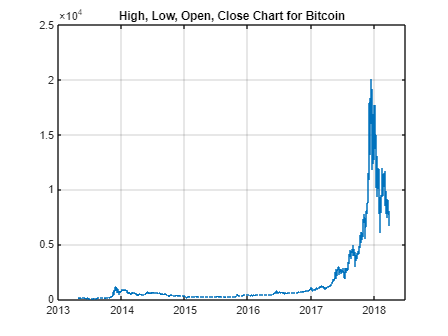

title('High, Low, Open, Close Chart for Bitcoin')

highlow(testData)

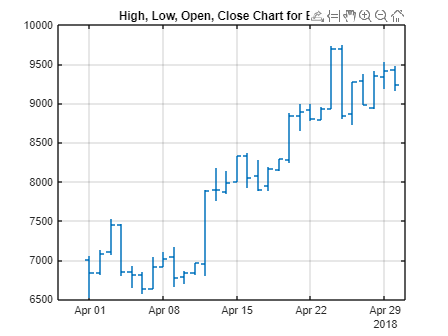

title('High, Low, Open, Close Chart for Bitcoin')

Let's test our strategy